clear all ; clc
syms t ;xi=[0;0;0;0];
A=[ 0 0 1 0; 0 0 0 1; 0 0 0 0; 0 0 0 0]; % The A matrix of one-dimensional motion
B=[0 0; 0 0 ;1 0; 0 1];
Bt=B.';          %Transpose of matrix B
F=expm(A*t)      %exponent of matrix

$$F = \left(\begin{array}{cccc} 1 & 0 & t & 0\\ 0 & 1 & 0 & t\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Ft=F.';
T=0.1;sigx=.75;sigy=.75;%Transpose of matrix e^at
cov=[sigx^2 0 ;0 sigy^2];      %covarience of noise
k=F*B*cov*Bt*Ft;
% clear B Bt Ft t
%covarience marix
Q=double(int(k,0 ,T));
U=chol(Q)';
F = double(subs(F,t,T))

F =     1.0000         0    0.1000         0
         0    1.0000         0    0.1000
         0         0    1.0000         0
         0         0         0    1.0000


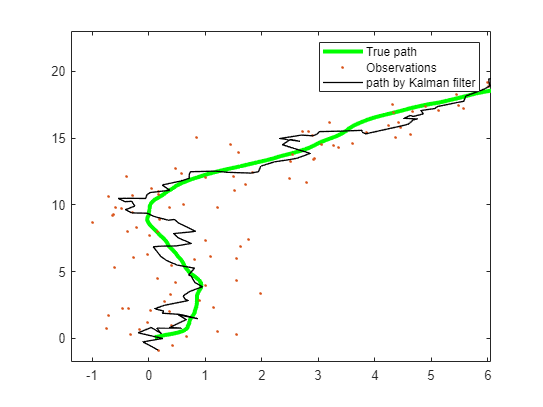

Xk =[];
Xhat =[];
xk=[0;0;1;1];
Yk=[];
sigm2=1/2;
R=[sigm2 0;0 sigm2];
V=chol(R);
Phat=eye(4)*10;
xhat=zeros(4,1);
for k= 1 : 100
    zk = randn(4,1);
    qk = U*zk;
    xk = F*xk+qk;
    Xk = [Xk xk];

    mk=V*randn(2,1);
    H=[1 0 0 0;0 1 0 0];
    yk=H*xk+mk;
    Yk=[Yk yk];

    xtemp=F*xhat;
    Ptemp=F*Phat*F'+Q;

    ytemp=H*xtemp;
    S=H*Ptemp*H'+R;
    K=Ptemp*H'/S;


    xhat=xtemp+K*(yk-ytemp);
    Phat=Ptemp-K*H*Ptemp;
    Xhat = [Xhat xhat];

end
figure
plot(Xk(1,:),Xk(2,:),'g-','LineWidth',3)
hold on
plot(Yk(1,:),Yk(2,:),'.')
hold on
plot(Xhat(1,:),Xhat(2,:),'k-','LineWidth',1)
legend('True path','Observations','path by Kalman filter')